clc;clearvars;close all;


nodeA.x = 0;
nodeA.y = 0;
nodeB.x = 5;
nodeB.y = 0;
nodeC.x = 1;
nodeC.y = 4;

nodes = [nodeA, nodeB, nodeC]

nodes = 1×3 struct array with fields:
    x
    y



area = getArea(nodes);

## Triangle

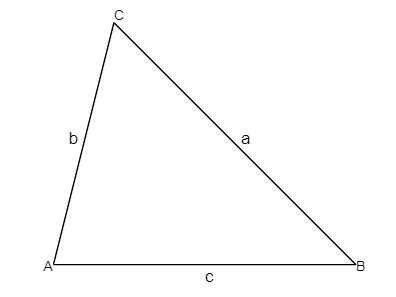

plot([nodes(1).x, nodes(2).x], [nodes(1).y, nodes(2).y],'Color','k')
hold on
plot([nodes(2).x, nodes(3).x], [nodes(2).y, nodes(3).y],'Color','k')
plot([nodes(3).x, nodes(1).x], [nodes(3).y, nodes(1).y],'Color','k')
hold off
text(nodeA.x, nodeA.y, "A",'HorizontalAlignment','right','FontSize',12)
text(nodeB.x, nodeB.y, "B",'HorizontalAlignment','left','FontSize',12)
text(nodeC.x, nodeC.y, "C",'VerticalAlignment','bottom','FontSize',12)
text((nodeB.x+nodeC.x)/2 + 0.1, (nodeB.y+nodeC.y)/2 + 0.1, "a",'HorizontalAlignment','left','FontSize',14)
text((nodeC.x+nodeA.x)/2 - 0.1, (nodeC.y+nodeA.y)/2 + 0.1, "b",'HorizontalAlignment','right','FontSize',14)
text((nodeA.x+nodeB.x)/2, (nodeA.y+nodeB.y)/2, "c","VerticalAlignment","top",'FontSize',14)

set(gca,'visible', 'off')
axis equal;

### Fermat Point

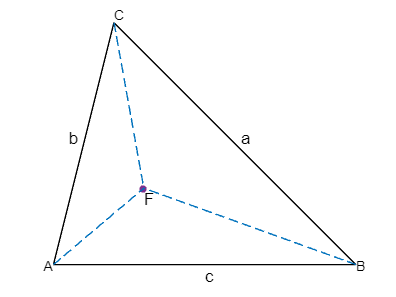

plot([nodes(1).x, nodes(2).x], [nodes(1).y, nodes(2).y],'Color','k')
hold on
plot([nodes(2).x, nodes(3).x], [nodes(2).y, nodes(3).y],'Color','k')
plot([nodes(3).x, nodes(1).x], [nodes(3).y, nodes(1).y],'Color','k')
hold off
text(nodeA.x, nodeA.y, "A",'HorizontalAlignment','right','FontSize',12)
text(nodeB.x, nodeB.y, "B",'HorizontalAlignment','left','FontSize',12)
text(nodeC.x, nodeC.y, "C",'VerticalAlignment','bottom','FontSize',12)
text((nodeB.x+nodeC.x)/2 + 0.1, (nodeB.y+nodeC.y)/2 + 0.1, "a",'HorizontalAlignment','left','FontSize',14)
text((nodeC.x+nodeA.x)/2 - 0.1, (nodeC.y+nodeA.y)/2 + 0.1, "b",'HorizontalAlignment','right','FontSize',14)
text((nodeA.x+nodeB.x)/2, (nodeA.y+nodeB.y)/2, "c","VerticalAlignment","top",'FontSize',14)

set(gca,'visible', 'off')
axis equal;
hold on

fermat = fermatPoint(nodes);
scatter(fermat.x,fermat.y,"filled")
text(fermat.x, fermat.y, "F","VerticalAlignment","top",'FontSize',14)

plot([nodes(1).x,fermat.x], [nodes(1).y,fermat.y], 'Color',[0,0.447,0.741],'LineStyle','--')
plot([nodes(2).x,fermat.x], [nodes(2).y,fermat.y], 'Color',[0,0.447,0.741],'LineStyle','--')
plot([nodes(3).x,fermat.x], [nodes(3).y,fermat.y], 'Color',[0,0.447,0.741],'LineStyle','--')

hold off

### Centriod Point

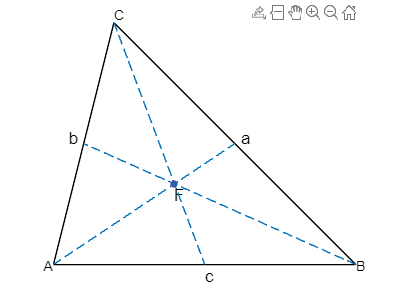


plot([nodes(1).x, nodes(2).x], [nodes(1).y, nodes(2).y],'Color','k')
hold on
plot([nodes(2).x, nodes(3).x], [nodes(2).y, nodes(3).y],'Color','k')
plot([nodes(3).x, nodes(1).x], [nodes(3).y, nodes(1).y],'Color','k')
hold off
text(nodeA.x, nodeA.y, "A",'HorizontalAlignment','right','FontSize',12)
text(nodeB.x, nodeB.y, "B",'HorizontalAlignment','left','FontSize',12)
text(nodeC.x, nodeC.y, "C",'VerticalAlignment','bottom','FontSize',12)
text((nodeB.x+nodeC.x)/2 + 0.1, (nodeB.y+nodeC.y)/2 + 0.1, "a",'HorizontalAlignment','left','FontSize',14)
text((nodeC.x+nodeA.x)/2 - 0.1, (nodeC.y+nodeA.y)/2 + 0.1, "b",'HorizontalAlignment','right','FontSize',14)
text((nodeA.x+nodeB.x)/2, (nodeA.y+nodeB.y)/2, "c","VerticalAlignment","top",'FontSize',14)

set(gca,'visible', 'off')
axis equal;


hold on
centriode = Centriod(nodes);
middle_a = middlePoint(nodes(2),nodes(3));
middle_b = middlePoint(nodes(3),nodes(1));
middle_c = middlePoint(nodes(1),nodes(2));
scatter(centriode.x,centriode.y,"filled")

text(centriode.x, centriode.y, "F","VerticalAlignment","top",'FontSize',14)
plot([nodes(1).x,middle_a.x], [nodes(1).y,middle_a.y], 'Color',[0,0.447,0.741],'LineStyle','--')
plot([nodes(2).x,middle_b.x], [nodes(2).y,middle_b.y], 'Color',[0,0.447,0.741],'LineStyle','--')
plot([nodes(3).x,middle_c.x], [nodes(3).y,middle_c.y], 'Color',[0,0.447,0.741],'LineStyle','--')

hold off

### Circumcenter Point


plot([nodes(1).x, nodes(2).x], [nodes(1).y, nodes(2).y],'Color','k')
hold on
plot([nodes(2).x, nodes(3).x], [nodes(2).y, nodes(3).y],'Color','k')
plot([nodes(3).x, nodes(1).x], [nodes(3).y, nodes(1).y],'Color','k')
hold off
text(nodeA.x, nodeA.y, "A",'HorizontalAlignment','right','FontSize',12)
text(nodeB.x, nodeB.y, "B",'HorizontalAlignment','left','FontSize',12)
text(nodeC.x, nodeC.y, "C",'VerticalAlignment','bottom','FontSize',12)
text((nodeB.x+nodeC.x)/2 + 0.1, (nodeB.y+nodeC.y)/2 + 0.1, "a",'HorizontalAlignment','left','FontSize',14)
text((nodeC.x+nodeA.x)/2 - 0.1, (nodeC.y+nodeA.y)/2 + 0.1, "b",'HorizontalAlignment','right','FontSize',14)
text((nodeA.x+nodeB.x)/2, (nodeA.y+nodeB.y)/2, "c","VerticalAlignment","top",'FontSize',14)

set(gca,'visible', 'off')



hold on
axis equal;
circumCenter = CircumCenter(nodes);
scatter(circumCenter.x,circumCenter.y,"filled")
text(circumCenter.x, circumCenter.y, "F","VerticalAlignment","top",'FontSize',14)

radium = getDistance(circumCenter, nodes(1))

radium = 2.9155

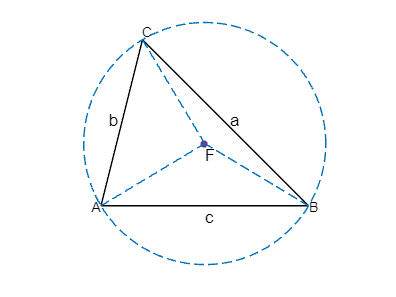

plotCircle(circumCenter.x, circumCenter.y, radium);
plot([nodes(1).x,circumCenter.x], [nodes(1).y,circumCenter.y], 'Color',[0,0.447,0.741],'LineStyle','--')
plot([nodes(2).x,circumCenter.x], [nodes(2).y,circumCenter.y], 'Color',[0,0.447,0.741],'LineStyle','--')
plot([nodes(3).x,circumCenter.x], [nodes(3).y,circumCenter.y], 'Color',[0,0.447,0.741],'LineStyle','--')


hold off

### OrthoCenter Point

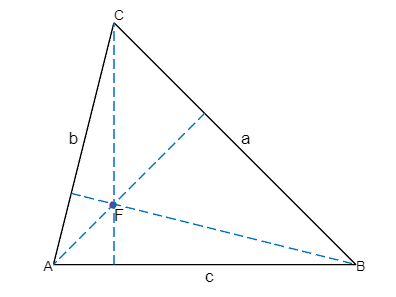


plot([nodes(1).x, nodes(2).x], [nodes(1).y, nodes(2).y],'Color','k')
hold on
plot([nodes(2).x, nodes(3).x], [nodes(2).y, nodes(3).y],'Color','k')
plot([nodes(3).x, nodes(1).x], [nodes(3).y, nodes(1).y],'Color','k')
hold off
text(nodeA.x, nodeA.y, "A",'HorizontalAlignment','right','FontSize',12)
text(nodeB.x, nodeB.y, "B",'HorizontalAlignment','left','FontSize',12)
text(nodeC.x, nodeC.y, "C",'VerticalAlignment','bottom','FontSize',12)
text((nodeB.x+nodeC.x)/2 + 0.1, (nodeB.y+nodeC.y)/2 + 0.1, "a",'HorizontalAlignment','left','FontSize',14)
text((nodeC.x+nodeA.x)/2 - 0.1, (nodeC.y+nodeA.y)/2 + 0.1, "b",'HorizontalAlignment','right','FontSize',14)
text((nodeA.x+nodeB.x)/2, (nodeA.y+nodeB.y)/2, "c","VerticalAlignment","top",'FontSize',14)

set(gca,'visible', 'off')



hold on
axis equal;
orthoCenter = OrthoCenter(nodes);
scatter(orthoCenter.x,orthoCenter.y,"filled")
text(orthoCenter.x, orthoCenter.y, "F","VerticalAlignment","top",'FontSize',14)

plotHeight(nodes(1),[nodes(2),nodes(3)])
plotHeight(nodes(2),[nodes(3),nodes(1)])
plotHeight(nodes(3),[nodes(1),nodes(2)])

hold off

### InCenter Point

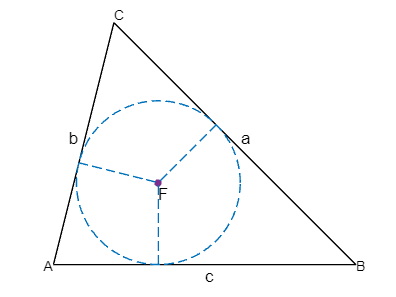


plot([nodes(1).x, nodes(2).x], [nodes(1).y, nodes(2).y],'Color','k')
hold on
plot([nodes(2).x, nodes(3).x], [nodes(2).y, nodes(3).y],'Color','k')
plot([nodes(3).x, nodes(1).x], [nodes(3).y, nodes(1).y],'Color','k')
hold off
text(nodeA.x, nodeA.y, "A",'HorizontalAlignment','right','FontSize',12)
text(nodeB.x, nodeB.y, "B",'HorizontalAlignment','left','FontSize',12)
text(nodeC.x, nodeC.y, "C",'VerticalAlignment','bottom','FontSize',12)
text((nodeB.x+nodeC.x)/2 + 0.1, (nodeB.y+nodeC.y)/2 + 0.1, "a",'HorizontalAlignment','left','FontSize',14)
text((nodeC.x+nodeA.x)/2 - 0.1, (nodeC.y+nodeA.y)/2 + 0.1, "b",'HorizontalAlignment','right','FontSize',14)
text((nodeA.x+nodeB.x)/2, (nodeA.y+nodeB.y)/2, "c","VerticalAlignment","top",'FontSize',14)

set(gca,'visible', 'off')



hold on
axis equal;
inCenter = InCenter(nodes);
scatter(inCenter.x,inCenter.y,"filled")
text(inCenter.x, inCenter.y, "F","VerticalAlignment","top",'FontSize',14)

radium = inCenter.y;
plotCircle(inCenter.x, inCenter.y, radium);
plotHeight(inCenter,[nodes(2),nodes(3)])
plotHeight(inCenter,[nodes(3),nodes(1)])
plotHeight(inCenter,[nodes(1),nodes(2)])
hold off

function plotCircle(x, y, r)
    theta = linspace(0, 2*pi, 1000); 
    x = x + r * cos(theta);
    y = y + r * sin(theta);
    plot(x, y, 'Color',[0,0.447,0.741], 'LineStyle','--'); 
end
function plotHeight(node, segment_nodes)

    k_segment = (segment_nodes(2).y - segment_nodes(1).y) / (segment_nodes(2).x - segment_nodes(1).x); % Slope of the segment
    b_segment = segment_nodes(1).y - k_segment * segment_nodes(1).x; % Intercept of the segment
        
    % if the height is vertical
    if k_segment == 0
        x_height = node.x;
        y_height = x_height*k_segment + b_segment; 
    else
        k_height = -1/k_segment;
        b_height = node.y - k_height * node.x; % Intercept of the segment
        syms x
        x_height = solve(x*k_segment + b_segment == x*k_height + b_height,x);
        y_height = x_height*k_segment + b_segment; 
    end
    plot([x_height, node.x], [y_height, node.y], 'Color',[0,0.447,0.741],'LineStyle','--');
end

function tc = tc_Fermat(area, s, t, u)
    m = 4*area + sqrt(3)*(s*s + t*t - u*u);
    n = 4*area + sqrt(3)*(s*s - t*t + u*u);
    v = 8*area*(12*area + sqrt(3)*(s*s + t*t + u*u));
    tc = (m*n)/v;
end
function area = getArea(nodes)
    area = abs((nodes(1).y + nodes(2).y)*(nodes(1).x - nodes(2).x) + ...
               (nodes(2).y + nodes(3).y)*(nodes(2).x - nodes(3).x) + ...
               (nodes(3).y + nodes(1).y)*(nodes(3).x - nodes(1).x))/2;
end
function point = middlePoint(node1, node2)
    point.x = (node1.x + node2.x)/2;
    point.y = (node1.y + node2.y)/2;
end
function distance = getDistance(node1, node2)
    distance = sqrt((node2.x - node1.x)^2 + (node2.y - node1.y)^2);
end
function point = fermatPoint(nodes)
    area = getArea(nodes);
    point.x = tc_Fermat(area, getDistance(nodes(1),nodes(2)), getDistance(nodes(2),nodes(3)), getDistance(nodes(3),nodes(1))) ...
                            * nodes(3).x + ...
              tc_Fermat(area, getDistance(nodes(2),nodes(3)), getDistance(nodes(3),nodes(1)), getDistance(nodes(1),nodes(2))) ...
                            * nodes(1).x + ...
              tc_Fermat(area, getDistance(nodes(3),nodes(1)), getDistance(nodes(1),nodes(2)), getDistance(nodes(2),nodes(3))) ...
                            * nodes(2).x;
    point.y = tc_Fermat(area, getDistance(nodes(1),nodes(2)), getDistance(nodes(2),nodes(3)), getDistance(nodes(3),nodes(1))) ...
                            * nodes(3).y + ...
              tc_Fermat(area, getDistance(nodes(2),nodes(3)), getDistance(nodes(3),nodes(1)), getDistance(nodes(1),nodes(2))) ...
                            * nodes(1).y + ...
              tc_Fermat(area, getDistance(nodes(3),nodes(1)), getDistance(nodes(1),nodes(2)), getDistance(nodes(2),nodes(3))) ...
                            * nodes(2).y;
end
function point = Centriod(nodes)
    point.x = (nodes(1).x + nodes(2).x + nodes(3).x) / 3;
    point.y = (nodes(1).y + nodes(2).y + nodes(3).y) / 3;
end
function point = CircumCenter(nodes)
    x1 = nodes(1).x;
    x2 = nodes(2).x;
    x3 = nodes(3).x;
    y1 = nodes(1).y;
    y2 = nodes(2).y;
    y3 = nodes(3).y;

    point.x = (x1^2*y2 - x1^2*y3 - x2^2*y1 + x2^2*y3 + x3^2*y1 - x3^2*y2 + y1^2*y2 - y1^2*y3 - y1*y2^2 + y1*y3^2 + y2^2*y3 - y2*y3^2) ...
            / (2*(x1*y2 - x2*y1 - x1*y3 + x3*y1 + x2*y3 - x3*y2));
    
    point.y = (-x1^2*x2 + x1^2*x3 + x1*x2^2 - x1*x3^2 + x1*y2^2 - x1*y3^2 - x2^2*x3 + x2*x3^2 - x2*y1^2 + x2*y3^2 + x3*y1^2 - x3*y2^2) ...
            / (2*(x1*y2 - x2*y1 - x1*y3 + x3*y1 + x2*y3 - x3*y2));
end
function point = OrthoCenter(nodes)
    % Extracting x and y coordinates from the nodes
    x1 = nodes(1).x;
    x2 = nodes(2).x;
    x3 = nodes(3).x;
    y1 = nodes(1).y;
    y2 = nodes(2).y;
    y3 = nodes(3).y;

    point.x = (y1*y2*y2 - y1*y1*y2 - y1*y3*y3 + y1*y1*y3 + y2*y3*y3 - y2*y2*y3 - x1*x2*y1 + x1*x2*y2 + x1*x3*y1 - x1*x3*y3 - x2*x3*y2 + x2*x3*y3) ...
              /(x1*y2 - x2*y1 - x1*y3 + x3*y1 + x2*y3 - x3*y2);

    % Calculating y_ortho
    point.y = -(x1*x2*x2 - x1*x1*x2 - x1*x3*x3 + x1*x1*x3 + x2*x3*x3 - x2*x2*x3 - x1*y1*y2 + x1*y1*y3 + x2*y1*y2 - x2*y2*y3 - x3*y1*y3 + x3*y2*y3) ...
              /(x1*y2 - x2*y1 - x1*y3 + x3*y1 + x2*y3 - x3*y2);
end
function point = InCenter(nodes)
    a = getDistance(nodes(2),nodes(3));
    b = getDistance(nodes(3),nodes(1));
    c = getDistance(nodes(1),nodes(2));
    
    A = nodes(1);B = nodes(2);C = nodes(3);


    point.x = (a*A.x + b*B.x + c*C.x) / (a + b + c);
    point.y = (a*A.y + b*B.y + c*C.y) / (a + b + c);
end